 clear all
close all
load TR4_data.mat

## calcolo punti

Npoint=1e9;
N1=ceil(Npoint^(1/3));
N2=ceil(Npoint^(1/3));
N3=ceil(Npoint^(1/3));
point=zeros(4,Npoint);
i=1;
for q1 = linspace(-Con(1,1)/2,Con(1,1)/2,N1)
    for q2 = linspace(-Con(1,2)/2,Con(1,2)/2,N2)
        for q3 = linspace(-Con(1,3)/2,Con(1,3)/2,N3)
            point(:,i)=TR4_dirKin([q1 q2 q3]',link);
            i=i+1;
        end
    end
end
%plot3(point(1,:),point(2,:),point(3,:),".")

## save punti

%save TR4_wk_points point

## calcolo minimi massimi

%load TR4_wk_points.mat
div=200;
Xdiv=div;Ydiv=div;Zdiv=div;
xmax=max(point(1,:));
xmin=min(point(1,:));
ymax=max(point(2,:));
ymin=min(point(2,:));
zmax=max(point(3,:));
zmin=min(point(3,:));
X=linspace(xmin,xmax,Xdiv);
dx=X(2)-X(1);
Y=linspace(ymin,ymax,Ydiv);
dy=Y(2)-Y(1);
Z=linspace(zmin,zmax,Zdiv);
dz=Z(2)-Z(1);

## Ricerca superficie metodo2

space=zeros(Xdiv,Ydiv,Zdiv);
for p=point
    x=p(1);
    y=p(2);
    z=p(3);
    xinf=find(X<=x);
    xinf=xinf(end);
    yinf=find(Y<=y);
    yinf=yinf(end);
    zinf=find(Z<=z);
    zinf=zinf(end);
    space(xinf,yinf,zinf)=1;
end

## Svuotamento

space_=zeros(Xdiv,Ydiv,Zdiv);
space_empty=zeros(Xdiv,Ydiv,Zdiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_(i,j,k)=1;
                else
                    space_empty(i,j,k)=1;
                end
            end
        end
    end
end
space_(1,1,:)=space(1,1,:);

Unable to perform assignment because the size of the left side is 1-by-1-by-199 and the size of the right side is 1-by-1-by-200.

space_(end,end,:)=space(end,end,:);
space_(1,:,1)=space(1,:,1);
space_(end,:,end)=space(end,:,end);
space_(:,1,1)=space(:,1,1);
space_(:,end,end)=space(:,end,end);

## plot

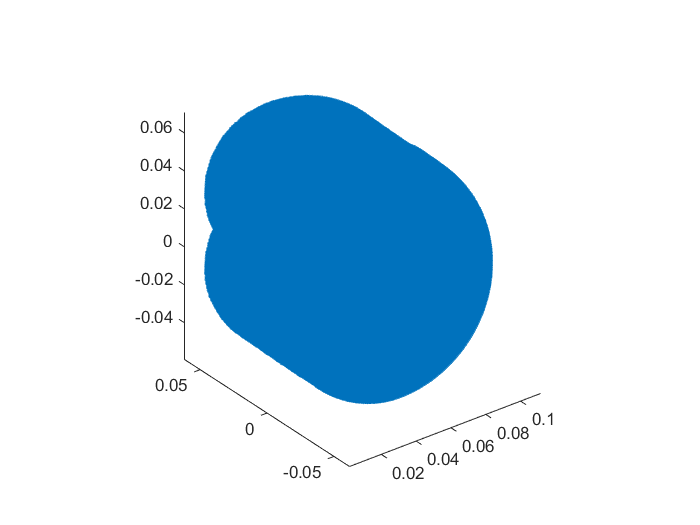

close all
point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space_(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal

## 2D

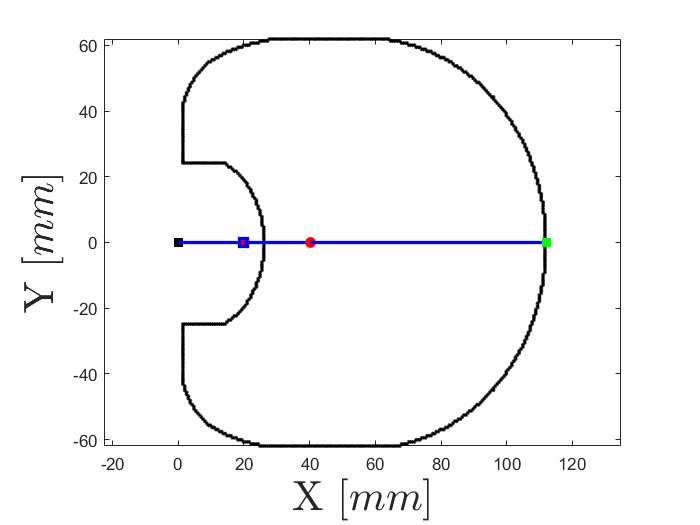

clear all
close all
load TR4_data.mat
load TR4_ws_dv_constrain.mat
X=X*1000;Y=Y*1000;Z=Z*1000;link=link*1000;offset=offset*1000;
space_XY=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_XY(i,j)=1;
                end
            end
        end
    end
end
space_XY_ext=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
            if(space_XY(i,j)==1)
                if(space_XY(i-1,j)==0 || space_XY(i,j-1)==0 ||  space_XY(i+1,j)==0 || space_XY(i,j+1)==0)
                    space_XY_ext(i,j)=1;
                end
            end
    end
end
p=1;
point2plot=nan(2,Xdiv*Ydiv);
for i = 1:Xdiv
    for j = 1:Ydiv
        if(space_XY_ext(i,j)==1)
            point2plot(:,p)=[X(i) Y(j)]';
            p=p+1;
        end
    end
end
figure(1)
plot(point2plot(1,:),point2plot(2,:),'k.')
hold on
TR4_plot_cXY(link,[0 0 0],1,offset,0);
axis equal
xlabel("X $[mm]$","FontSize",25,"Interpreter","latex")
ylabel("Y $[mm]$","FontSize",25,"Interpreter","latex")

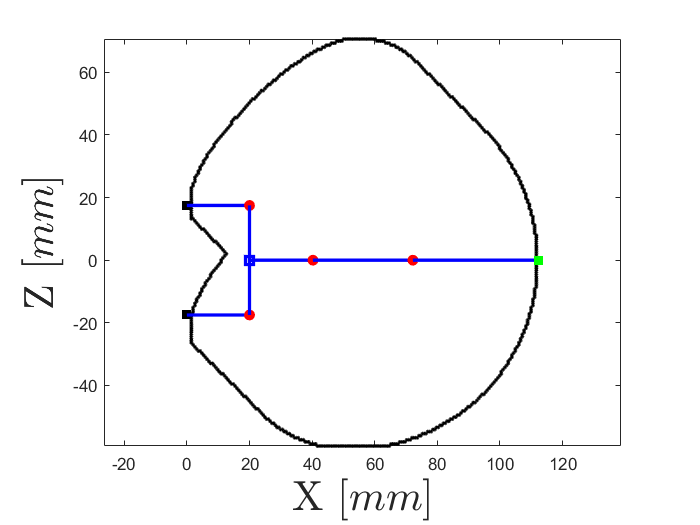



space_XZ=zeros(Xdiv,Ydiv);
for i = 2:Xdiv-1
    for j = 2:Ydiv-1
        for k = 2:Zdiv-1
            if(space(i,j,k)==1)
                if(space(i-1,j,k)==0 || space(i,j-1,k)==0 || space(i,j,k-1)==0 || space(i+1,j,k)==0 || space(i,j+1,k)==0 || space(i,j,k+1)==0)
                    space_XZ(i,k)=1;
                end
            end
        end
    end
end
space_XZ_ext=zeros(Xdiv,Zdiv);
for i = 2:Xdiv-1
    for j = 2:Zdiv-1
            if(space_XZ(i,j)==1)
                if(space_XZ(i-1,j)==0 || space_XZ(i,j-1)==0 ||  space_XZ(i+1,j)==0 || space_XZ(i,j+1)==0)
                    space_XZ_ext(i,j)=1;
                end
            end
    end
end
p=1;
point2plot=nan(2,Xdiv*Zdiv);
for i = 1:Xdiv
    for j = 1:Zdiv
        if(space_XZ_ext(i,j)==1)
            point2plot(:,p)=[X(i) Z(j)]';
            p=p+1;
        end
    end
end
figure(2)
plot(point2plot(1,:),point2plot(2,:),'k.')
hold on
TR4_plot_cXZ(link,[0 0 0],2,offset,0);
axis equal
xlabel("X $[mm]$","FontSize",25,"Interpreter","latex")
ylabel("Z $[mm]$","FontSize",25,"Interpreter","latex")

## plot slice

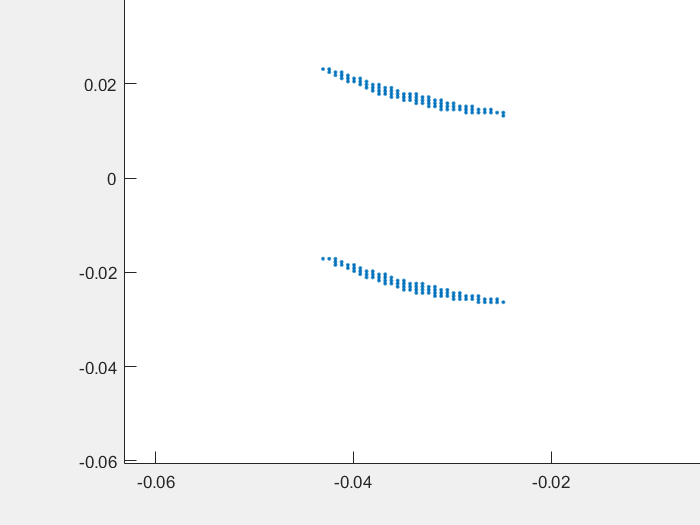

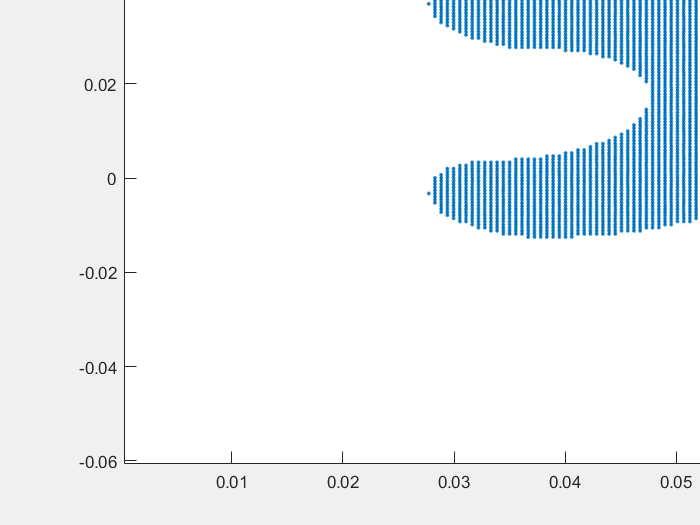

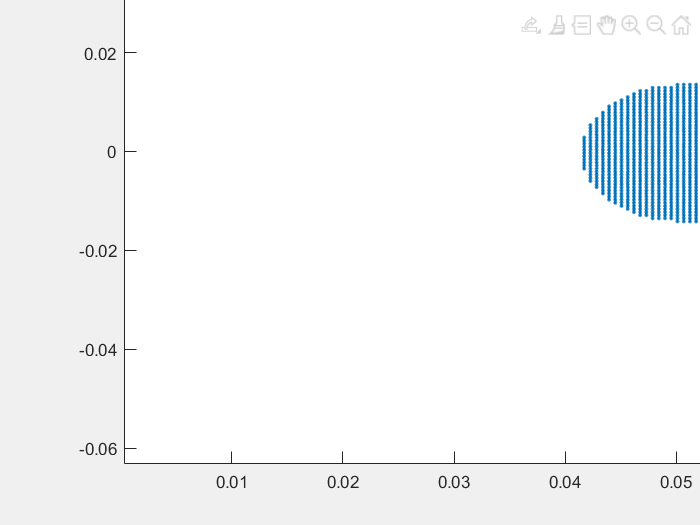

load TR4_ws_dv_constrain.mat
sliderX(space,Xdiv,X,Y,Z)
sliderY(space,Ydiv,X,Y,Z)
sliderZ(space,Zdiv,X,Y,Z)

## save

save TR4_ws_dv_constrain space Xdiv Ydiv Zdiv X Y Z space_ space_empty

## ricerca superficie metodo1

% Zsup=zeros(Xdiv,Ydiv)+0.035;
% Zinf=zeros(Xdiv,Ydiv)+0.035;
% 
% for p=point
%     x=p(1);
%     y=p(2);
%     z=p(3);
%     xinf=find(X<=x);
%     xinf=xinf(end);
%     yinf=find(Y<=y);
%     yinf=yinf(end);
%     if(Zsup(xinf,yinf)<z)
%         Zsup(xinf,yinf)=z;
%     end
%     if(Zinf(xinf,yinf)>z)
%         Zinf(xinf,yinf)=z;
%     end
% end

## Turn in point

% close all
% pointSup=zeros(3,Xdiv*Ydiv);
% z=1;
% for i = 1:Xdiv
%     for j = 1:Ydiv
%         if(Zsup(i,j)~=0.035)
%             pointSup(:,z)=[X(i) Y(j) Zsup(i,j)]';
%             z=z+1;
%         end
%     end
% end
% pointInf=zeros(3,Xdiv*Ydiv);
% z=1;
% for i = 1:Xdiv
%     for j = 1:Ydiv
%         if(Zinf(i,j)~=0.035)
%             pointInf(:,z)=[X(i) Y(j) Zinf(i,j)]';
%             z=z+1;
%         end
%     end
% end
% plot3(pointSup(1,:),pointSup(2,:),pointSup(3,:),'.-')
% hold on
% plot3(pointInf(1,:) ,pointInf(2,:) ,pointInf(3,:) ,'.-')
% 
% xlabel("X")
% ylabel("Z")
% zlabel("Y")
% axis equal